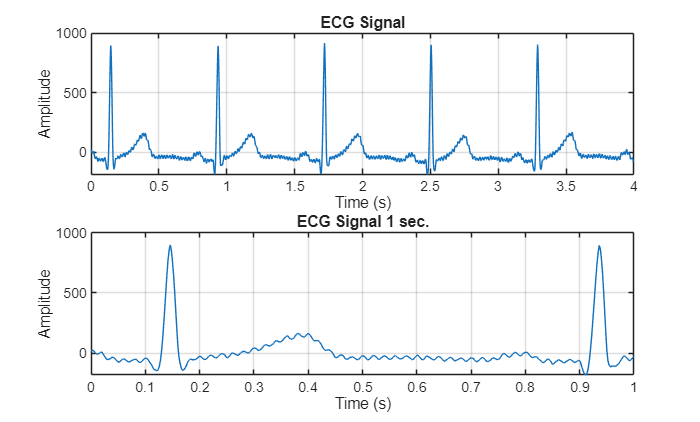

load('ecg_data_fixed.mat');
%1-> ecg
figure;
subplot(2,1,1); 
plot(t, y);
title('ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
%1.1-> ecg 1 sec
subplot(2,1,2);
plot(t, y);
xlim([0, 1]);
title('ECG Signal 1 sec.');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

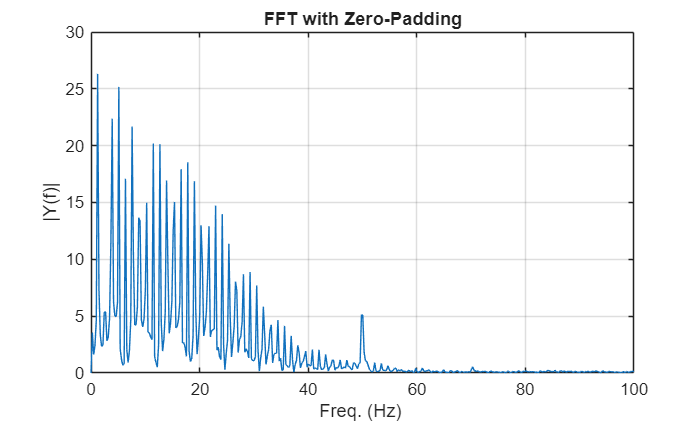

L=length(y);
N=2^nextpow2(L); 
Y=fft(y,N);
Y_abs=abs(Y)/L;
f=fs*(0:(N/2))/N; %frequency vector that goes from 0 to 250Hz (Nynquist) diffF=fs/N
figure;
plot(f,Y_abs(1:N/2+1)); %plot till 250Hz = half of the data
xlim([0 100]);
title('FFT with Zero-Padding');
xlabel('Freq. (Hz) ');
ylabel('|Y(f)|');
grid on;

%find f0-> fundamental harmonics-> f0 is the distance between the first to
%peaks->find peaks in the fft while ignoring 0Hz

[peaks, locs] = findpeaks(Y_abs(2:N/2+1), 'MinPeakHeight',0.1);
if isempty(locs)
    f0 = NaN;
else
% adjust locs index since we started from element 2
peaks_freq= f(locs+1);
end
harmonic=diff(peaks_freq);
f0=mean(harmonic);
fprintf('Estimated fundamental frequency f0 = %.4f Hz\n', f0);

Estimated fundamental frequency f0 = 1.9589 Hz


Tp=1/f0;
fprintf('Estimated period based on the fundamental frequency: Tp= %.4f s\n',Tp);

Estimated period based on the fundamental frequency: Tp= 0.5105 s


%knowing that 1Hz is 60bpm
Bpm=f0*60;
fprintf('Estimated Heart Rate based on the fundamental frequency: HR= %.4f bpm\n',Bpm);

Estimated Heart Rate based on the fundamental frequency: HR= 117.5363 bpm


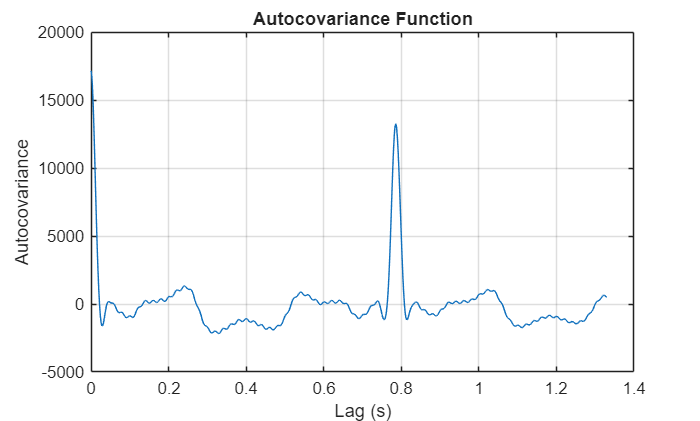

%Calculate the same using covf 
%Dont estimate k>N/3
L=length(y);
M=floor(L/3);
R=covf(y,M);

lag_sec = (0:length(R)-1) / fs; 

% Plot the autocovariance function
figure;
plot(lag_sec, R);
title('Autocovariance Function');
xlabel('Lag (s)');
ylabel('Autocovariance');
grid on;


% Ignore the first 0.4s to avoid lag 0
ignore_samples = round(0.4 * fs); 

[pk, locs] = findpeaks(R(ignore_samples:end)); 

if isempty(locs)
    fprintf('No valid peaks found in the autocovariance.\n');
else
    % global index 
    true_loc = locs(1) + ignore_samples - 1; 
        
    % first time a main peak happens = Tp
    Tp_cov = lag_sec(true_loc);
    f0_cov = 1 / Tp_cov;
     
    fprintf('Estimated fundamental frequency (ACF) f0_acf = %.4f Hz\n', f0_cov);
       fprintf('Estimated period (ACF) Tp_acf = %.4f s\n', Tp_cov); 
    fprintf('Estimated Heart Rate (ACF) HR_acf = %.4f bpm\n', f0_cov * 60);
end

Estimated fundamental frequency (ACF) f0_acf = 2.5000 Hz


Estimated period (ACF) Tp_acf = 0.4000 s


Estimated Heart Rate (ACF) HR_acf = 150.0000 bpm


% ECG Bandstop Butterworth Filter using buttord

Wp = [45 55] / (Fs/2);  % Passband edges (normalized)
Ws = [49 51] / (Fs/2);  % Stopband edges (normalized)


Rp = 3;    % Passband ripple in dB
Rs = 40;   % Stopband attenuation in dB

% minimum filter order and cutoff frequencies
[n, Wn] = buttord(Wp, Ws, Rp, Rs);

% Design Butterworth bandstop filter
[b, a] = butter(n, Wn, 'stop');


fprintf('Calculated filter parameter n: %d\n', n);

Calculated filter parameter n: 3


fprintf('Cutoff frequencies (normalized): %.6f, %.6f\n', Wn(1), Wn(2));

Cutoff frequencies (normalized): 0.182045, 0.219342


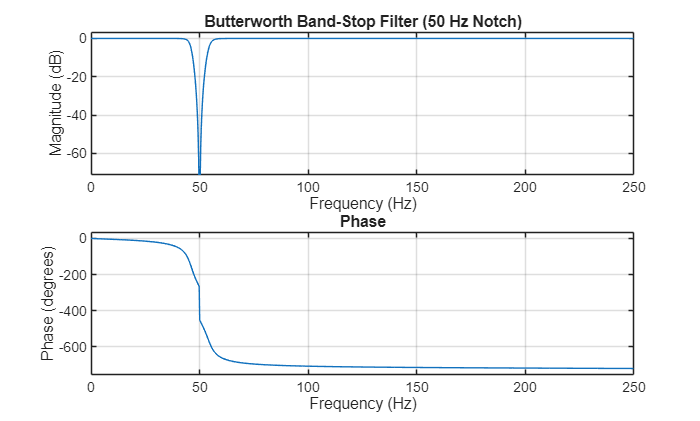


%freqz inspection
figure;
freqz(b, a, 1024, Fs);
title('Butterworth Band-Stop Filter (50 Hz Notch)');

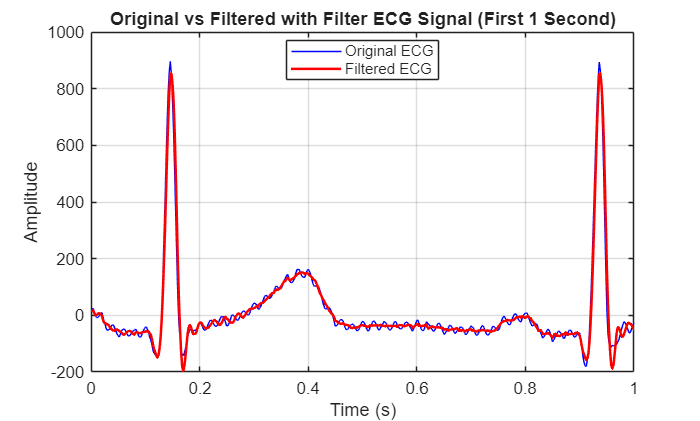



y_filter = filter(b, a, y);
figure;
plot(t, y, 'b', 'DisplayName', 'Original ECG');
hold on;
plot(t, y_filter, 'r', 'LineWidth', 1.5, 'DisplayName', 'Filtered ECG');
xlim([0, 1]); 

title('Original vs Filtered with Filter ECG Signal (First 1 Second)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Location', 'best');
grid on;

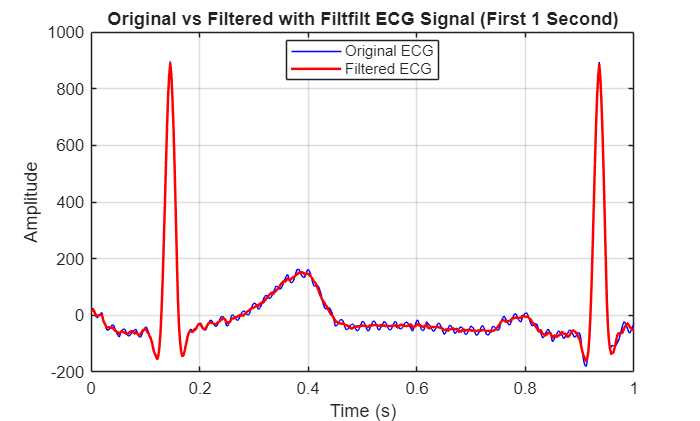


y_filtfilt = filtfilt(b, a, y);
figure;
plot(t, y, 'b', 'DisplayName', 'Original ECG');
hold on;
plot(t, y_filtfilt, 'r', 'LineWidth', 1.5, 'DisplayName', 'Filtered ECG');
xlim([0, 1]); 


title('Original vs Filtered with Filtfilt ECG Signal (First 1 Second)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Location', 'best');
grid on;

%FIR

% order->even number type I
N_fir = 400; 

% Freq normalized Nyquist (Fs/2 = 250 Hz)
% [0 to Pass1, Stop1 to Stop2, Pass2 to Nyquist]
F = [0, 45, 49, 51, 55, 250] / (Fs/2); 

% Amp(1 = pass, 0 = stop)
A = [1, 1, 0, 0, 1, 1];


% Weights: [Passband1, Stopband,Passband2]
W = [1, 50, 1]; 
b_fir = firls(N_fir, F, A, W);
a_fir = 1; 

fprintf('FIR Filter order N: %d\n', N_fir);

FIR Filter order N: 400


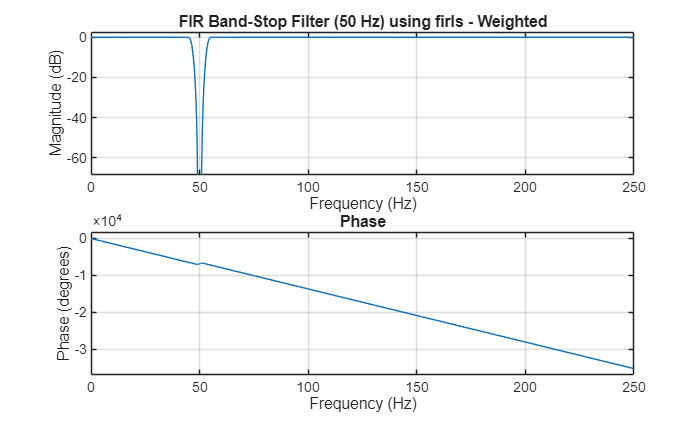



figure;
freqz(b_fir, a_fir, 1024, Fs);
title('FIR Band-Stop Filter (50 Hz) using firls - Weighted');

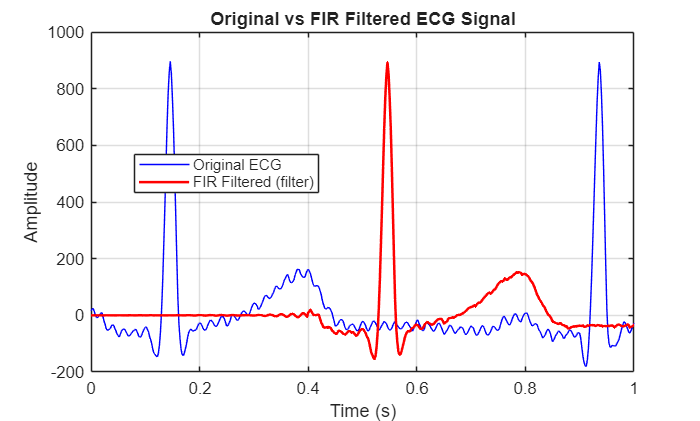


y_fir_filter = filter(b_fir, a_fir, y);

figure;
plot(t, y, 'b', 'DisplayName', 'Original ECG');
hold on;
plot(t, y_fir_filter, 'r', 'LineWidth', 1.5, 'DisplayName', 'FIR Filtered (filter)');
xlim([0, 1]); 
title('Original vs FIR Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Location', 'best');
grid on;